# 4.9. Цифровые цепи и [булева алгебра](https://ru.wikipedia.org/wiki/Булева_алгебра)

Булева алгебра

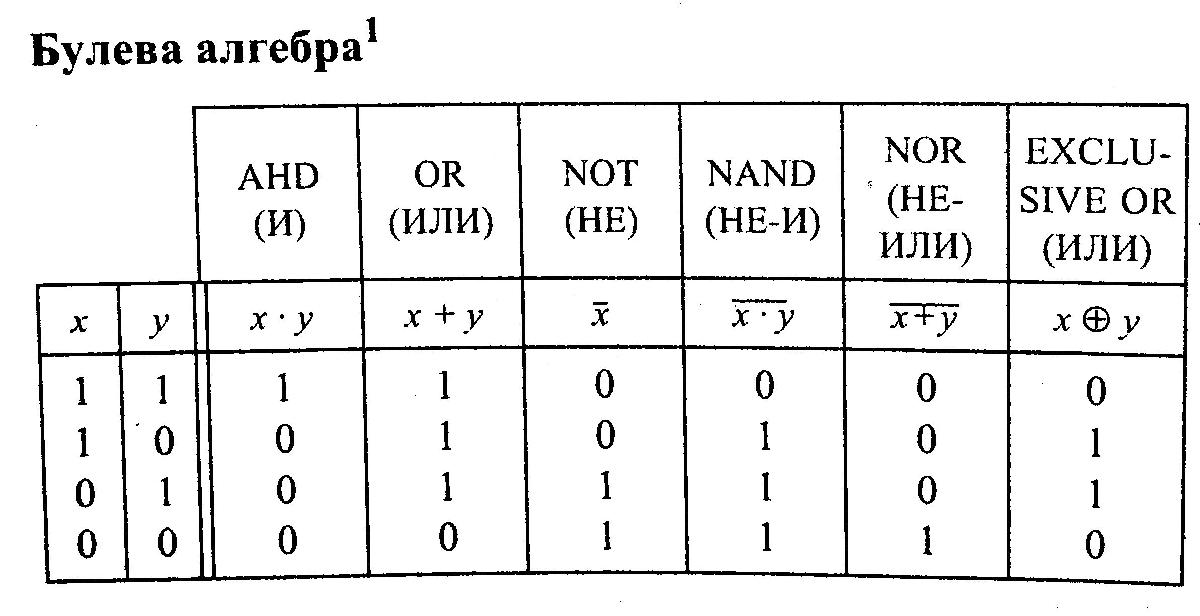

clear
X=logical([1 1 0 0])

X = 1×4 logical array
   1   1   0   0


Y=logical([1 0 1 0])

Y = 1×4 logical array
   1   0   1   0


and(X,Y)

ans = 1×4 logical array
   1   0   0   0


or(X,Y)

ans = 1×4 logical array
   1   1   1   0


not(X)

ans = 1×4 logical array
   0   0   1   1


not(and(X,Y))

ans = 1×4 logical array
   0   1   1   1


not(or(X,Y))

ans = 1×4 logical array
   0   0   0   1


xor(X,Y)

ans = 1×4 logical array
   0   1   1   0


#### [Законы де Моргана](https://ru.wikipedia.org/wiki/Законы_де_Моргана)


$$\overline{x+y} =\bar{x} \cdot \bar{y}$$


syms x y z logical
~(x+y)==(~x)&(~y)

$$ans = \neg y\wedge \left(\neg x+y\right)=\left(\neg x\right)$$


$$\overline{x\cdot y} =\overline{x} +\bar{y}$$


~(x&y)==~x+~y

$$ans = \left(\neg x\vee \neg y\right)=\left(\neg x\right)+\left(\neg y\right)$$

#### Консенсус


$$x\cdot y+\overline{x} \cdot z=x\cdot y+\bar{x} \cdot z+y\cdot z$$


(x&y)+(~x&z)==(x&y)+(~x&z)+(y&z)

$$ans = \left(x\wedge y\right)+\left(\neg x\wedge z\right)=\left(y\wedge z\right)+\left(x\wedge y\right)+\left(\neg x\wedge z\right)$$


$$\left(x+y\right)\cdot \left(\bar{x} +z\right)=\left(x+y\right)\cdot \left(\bar{x} +z\right)\cdot \left(y+z\right)$$


(x+y)&((~x)+z)==(x+y)&((~x)+z)&(y+z)

$$ans = x+y\wedge y+z\wedge \left(\neg x\right)+z=x+y\wedge \left(\neg x\right)+z$$

#### Поглощение


$$x+x\cdot y=x$$


x+(x&y)==x

$$ans = \left(x\wedge y\right)+x=x$$


$$x\cdot \left(x+y\right)=x$$


x&(x+y)==x

$$ans = x\wedge x+y=x$$

#### Сложение по модулю 2 и его инверсия


$$x\otimes y=x\cdot \bar{y} +\bar{x} \cdot y$$


xor(x,y)==(x&(~y))+((~x)&y)

$$ans = \left(x\mathrm{xor}y\right)=\left(x\wedge \neg y\right)+\left(\neg x\wedge y\right)$$


$$\overline{x\otimes y} =x\cdot y+\bar{x} \cdot \bar{y}$$


not(xor(x,y))==(x&y)+((~x)&(~y))

$$ans = \left(\neg \left(x\mathrm{xor}y\right)\right)=\left(x\wedge y\right)+\left(\neg x\wedge \neg y\right)$$

Таблица функций для SR, JK, T и D триггеров

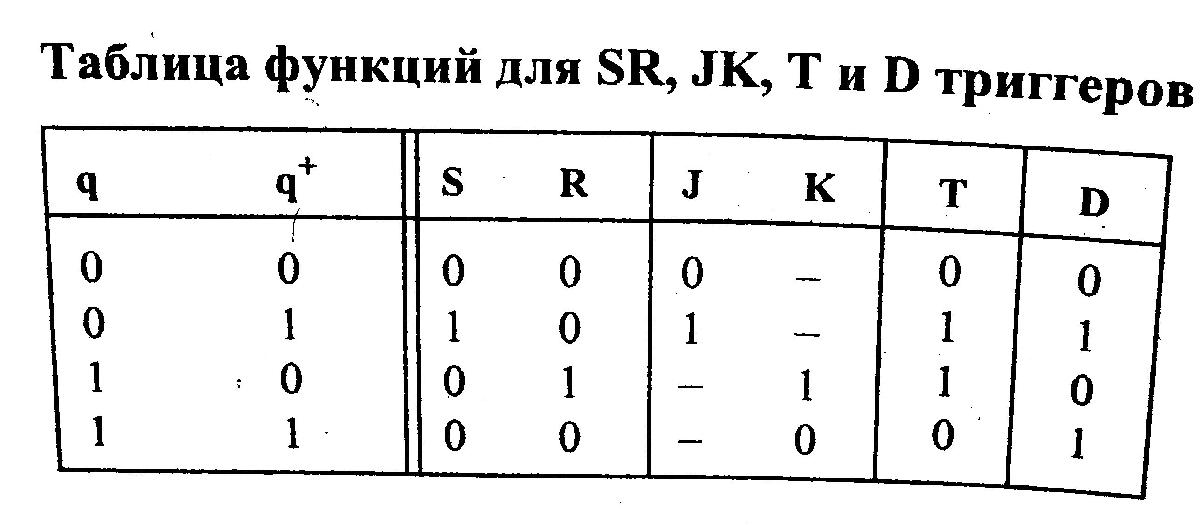

% q q+  S R  J K  T  D
% 0 0   0 0  0 -  0  0
% 0 1   1 0  1 -  1  1
% 1 0   0 1  - 1  1  0
% 1 1   0 0  - 0  0  1
% q+ = результат